# Simscape multibody model og Regbot in balance

initial setup with motor velocity controller this is intended as simulation base for balance control.

close all
clear

## Simulink model name

model='regbot_1mg';

## parameters for REGBOT

motor

RA = 3.3/2;    % ohm (2 motors)
JA = 1.3e-6*2; % motor inertia
LA = 6.6e-3/2; % rotor inductor (2 motors)
BA = 3e-6*2;   % rotor friction
Kemf = 0.0105; % motor constant
Km = Kemf;
% køretøj
NG = 9.69; % gear
WR = 0.03; % wheel radius
Bw = 0.155; % wheel distance
%
% model parts used in Simulink
mmotor = 0.193;   % total mass of motor and gear [kg]
mframe = 0.32;    % total mass of frame and base print [kg]
mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
mpdist =  0.10;   % distance to lit [m]
% disturbance position (Z)
pushDist = 0.1; % relative to motor axle [m]

## Own REGBOT parameters

RA = 6.4/2;    % ohm (2 motors)
JA = 1.3e-6*2; % motor inertia
LA = 6.6e-3/2; % rotor inductor (2 motors)
BA = 3e-6*2;   % rotor friction
Kemf = 0.008; % motor constant
Km = Kemf;
% køretøj
NG = 9.69; % gear
WR = 0.03; % wheel radius
Bw = 0.155; % wheel distance
%
% model parts used in Simulink
mmotor = 0.193;   % total mass of motor and gear [kg]
mframe = 0.32;    % total mass of frame and base print [kg]
mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
mpdist =  0.10;   % distance to lit [m]
% disturbance position (Z)
pushDist = 0.1; % relative to motor axle [m]

## Controller design parameters

% Wheel velocity to voltage
N_i_vu = 2;
gamma_vu = 90;

% Tilt to velocity controller
N_i_tv = 10;
gamma_tv = 60;
alpha_tv = 0.00001;

% Pre velocity to tilt controller
N_i_vreft = 4;
gamma_vreft = 360+70;
alpha_vreft = 0.3;

% position to pre velocity controller
gamma_xvref = 360+80;
alpha_xvref = 0.3;

## Sample controller values (initialisation)

K_vu = 15;     % Kp
t_i_vu = 0.05;   % Tau_i
Kffvu = 0;     % feed forward constant
startAngle = 10;  % tilt in degrees at time zero
twvlp = 0.005;    % velocity noise low pass filter time constant (recommended)
K_post = 1;
t_i_post = 1;
t_lead_tv = 0;
t_i_tv = 1;
K_tv = 1;
t_i_vreft = 1;
num_lead_vreft = 0;
den_lead_vreft = 1;
K_vreft = 1;
K_xvref = 1;
num_lead_xvref = 0;
den_lead_xvref = 1;

s = tf('s');

## Estimate transfer function for base system using LINEARIZE

Motor volatge to wheel velocity (wv)

load_system(model);
open_system(model);
% define points in model
ios(1) = linio(strcat(model,'/Limit9v'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gvu = minreal(tf(num, den))

Gvu =
 
                  5.351e05 s^3 + 5.351e08 s^2 - 3.873e07 s - 3.873e10
  -----------------------------------------------------------------------------------
  s^6 + 2888 s^5 + 2.213e06 s^4 + 3.435e08 s^3 + 1.417e09 s^2 - 5.737e10 s - 1.306e11
 
Continuous-time transfer function.
Model Properties


## Transfer function from previous exercise

Gvu = tf(2.183,[1 6.651]);

## Bodeplot

pole(Gvu)

ans = -6.6510

isstable(Gvu)

ans = logical
   1


h = figure(100)

h =   Figure (100) with properties:

      Number: 100
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


bode(Gvu)

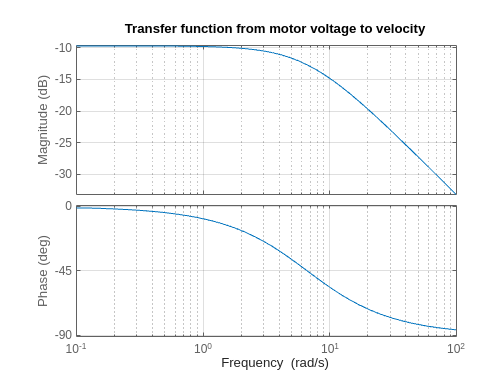

grid on
title('Transfer function from motor voltage to velocity')

% saveas(h, 'motor to velocity.png');

## PI-Controller for voltage to velocity

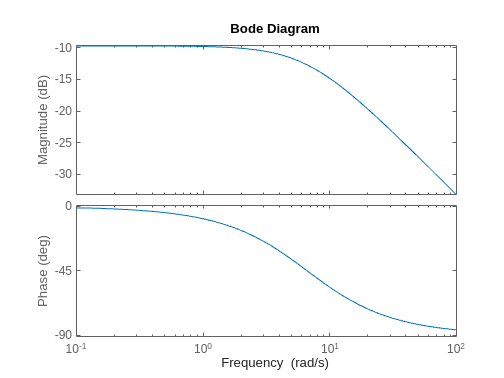

% Design parameters
N_i = N_i_vu;
gamma_m = gamma_vu;

phi_i = rad2deg(-atan(1/N_i));
phi_G = -180+gamma_m-phi_i;

bode(Gvu)

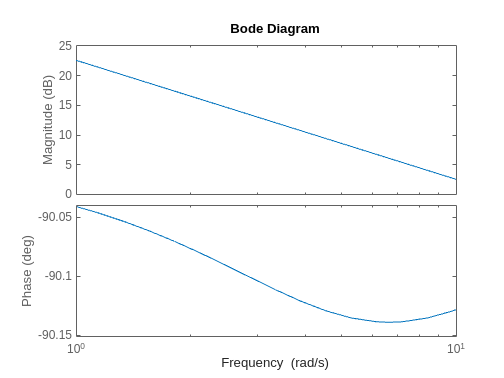


[mag,phase,wout] = bode(Gvu);
omega_c = interp1(squeeze(phase),wout,phi_G);
tau_i = N_i/omega_c;
C_i = tf([tau_i 1],[tau_i 0]);
Kp = 1/abs(freqresp(C_i*Gvu,omega_c*1i));
G_vu_ol = Kp*C_i*Gvu;
G_vu_cl = G_vu_ol/(1+G_vu_ol);
bode(G_vu_ol)

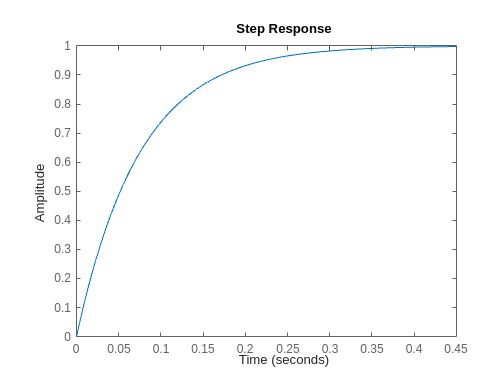

step(G_vu_cl)

## Flush values to model

K_vu = Kp

K_vu = 6.1172

t_i_vu = tau_i

t_i_vu = 0.1496

## **Transfer function from velocity to tilt using linearize**

% define points in model
ios(1) = linio(strcat(model,'/vel_cont'),1,'openinput');
ios(2) = linio(strcat(model, '/tilt_angle'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gtv = minreal(tf(num, den))

Gtv =
 
                 -1.831e05 s^4 - 2.371e08 s^3 - 4.143e10 s^2 - 2.665e11 s - 7.977e08
  --------------------------------------------------------------------------------------------------
  s^7 + 2888 s^6 + 2.213e06 s^5 + 3.468e08 s^4 + 4.712e09 s^3 - 3.573e10 s^2 - 3.691e11 s - 1.583e12
 
Continuous-time transfer function.


h = figure(100)

h =   Figure (100) with properties:

      Number: 100
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


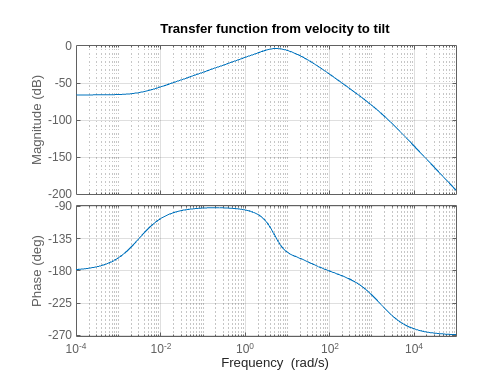

bode(-Gtv)
grid on
title('Transfer function from velocity to tilt')

[mag,phase,wout]=bode(Gtv);

## Post-Integrator

[gpeak,fpeak] = getPeakGain(-Gtv)

gpeak = 0.6762

fpeak = 5.3425

tau_i = 1/fpeak

tau_i = 0.1872

C_pi = -(tau_i*s+1)/(tau_i*s)

C_pi =
 
  -0.1872 s - 1
  -------------
    0.1872 s
 
Continuous-time transfer function.
Model Properties


G_post=Gtv*C_pi

G_post =
 
                3.427e04 s^5 + 4.457e07 s^4 + 7.992e09 s^3 + 9.131e10 s^2 + 2.666e11 s + 7.977e08
  -------------------------------------------------------------------------------------------------------------
  0.1872 s^8 + 540.6 s^7 + 4.142e05 s^6 + 6.491e07 s^5 + 8.82e08 s^4 - 6.689e09 s^3 - 6.908e10 s^2 - 2.964e11 s
 
Continuous-time transfer function.


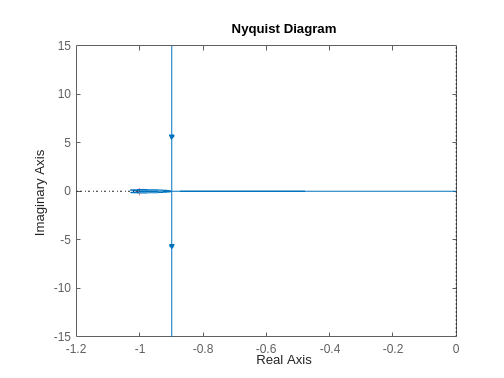

nyquist(G_post)

G_post_cl=minreal(G_post/(1+G_post))

G_post_cl =
 
                 1.831e05 s^5 + 2.381e08 s^4 + 4.27e10 s^3 + 4.878e11 s^2 + 1.425e12 s + 4.262e09
  ---------------------------------------------------------------------------------------------------------------
  s^8 + 2888 s^7 + 2.213e06 s^6 + 3.47e08 s^5 + 4.95e09 s^4 + 6.965e09 s^3 + 1.188e11 s^2 - 1.588e11 s + 4.262e09
 
Continuous-time transfer function.


isstable(G_post_cl)

ans = logical
   0


## Flush values to Simulink

K_post = -1

K_post = -1

t_i_post=tau_i

t_i_post = 0.1872

## Tilt to velocity controller PI-lead

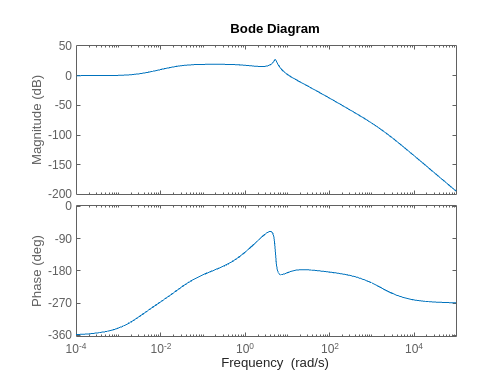

bode(G_post_cl)

% Design parameters
N_i = N_i_tv;
gamma_m = gamma_tv;
alpha = alpha_tv;


phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_post_cl);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  0.01574 s + 1
  -------------
    0.01574 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
   0.4977 s + 1
  ---------------
  4.977e-06 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_post_cl),omega_c);
Kp = 1/mag;

G_tv_ol = minreal(Kp*C_i*C_D*G_post_cl)

G_tv_ol =
 
             2.126e11 s^7 + 2.904e14 s^6 + 6.773e16 s^5 + 3.852e18 s^4 + 4.512e19 s^3 + 1.808e20 s^2 + 2.115e20 s + 6.318e17
  --------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 2.038e05 s^9 + 5.825e08 s^8 + 4.45e11 s^7 + 6.973e13 s^6 + 9.947e14 s^5 + 1.4e15 s^4 + 2.387e16 s^3 - 3.191e16 s^2 + 8.563e14 s
 
Continuous-time transfer function.


G_tv_cl = minreal(G_tv_ol/(1+G_tv_ol))

G_tv_cl =
 
                    2.126e11 s^7 + 2.904e14 s^6 + 6.773e16 s^5 + 3.852e18 s^4 + 4.512e19 s^3 + 1.808e20 s^2 + 2.115e20 s + 6.318e17
  ----------------------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 2.038e05 s^9 + 5.825e08 s^8 + 6.576e11 s^7 + 3.601e14 s^6 + 6.872e16 s^5 + 3.853e18 s^4 + 4.514e19 s^3 + 1.807e20 s^2 + 2.115e20 s + 6.318e17
 
Continuous-time transfer function.


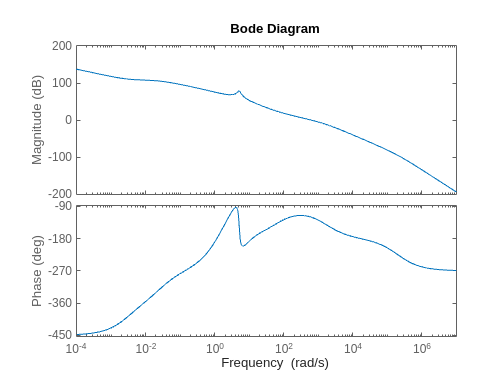


bode(G_tv_ol)

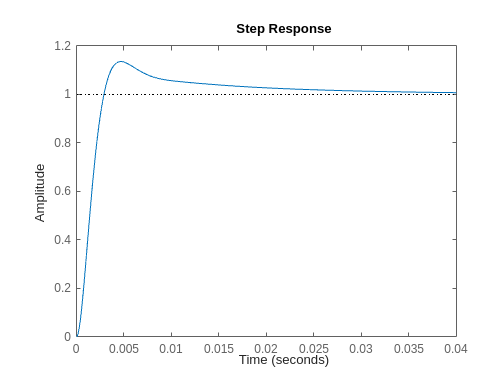

step(G_tv_cl)

## Flush values to simulink

t_lead_tv = tau_D;
t_i_tv = tau_i;
K_tv = Kp;

## Transfer function from reference tilt to velocity using linearize

% define points in model
ios(1) = linio(strcat(model,'/tilt_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
G_vreft = minreal(tf(num, den))

G_vreft =
 
                  -3.801e07 s^6 - 4.088e10 s^5 - 2.9e12 s^4 - 2.753e13 s^3 + 1.238e14 s^2 + 2.206e15 s + 6.241e15
  --------------------------------------------------------------------------------------------------------------------------------
  s^9 + 2888 s^8 + 3.271e06 s^7 + 1.789e09 s^6 + 3.385e11 s^5 + 1.911e13 s^4 + 2.244e14 s^3 + 8.996e14 s^2 + 1.053e15 s + 3.144e12
 
Continuous-time transfer function.


## Reference tilt to velocity controller

isstable(G_vreft)

ans = logical
   1


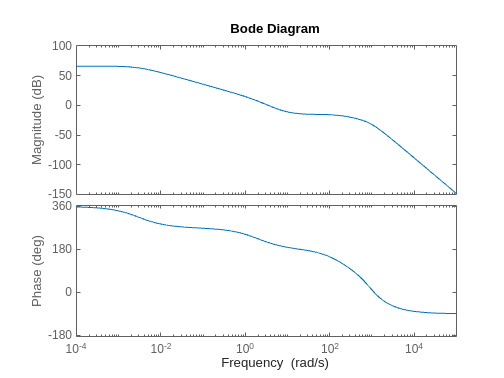

bode(G_vreft)



% Design parameters
N_i = N_i_vreft;
gamma_m = gamma_vreft;
alpha = alpha_vreft;


phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_vreft);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  2.525 s + 1
  -----------
    2.525 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  1.152 s + 1
  ------------
  0.3457 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_vreft),omega_c);
Kp = 1/mag;

G_vreft_ol = minreal(Kp*C_i*C_D*G_vreft)

G_vreft_ol =
 
             -2.209e07 s^8 - 2.379e10 s^7 - 1.715e12 s^6 - 1.814e13 s^5 + 5.117e13 s^4 + 1.368e15 s^3 + 5.273e15 s^2 + 5.025e15 s + 1.247e15
  -----------------------------------------------------------------------------------------------------------------------------------------------------
  s^11 + 2891 s^10 + 3.279e06 s^9 + 1.798e09 s^8 + 3.437e11 s^7 + 2.009e13 s^6 + 2.797e14 s^5 + 1.549e15 s^4 + 3.655e15 s^3 + 3.048e15 s^2 + 9.095e12 s
 
Continuous-time transfer function.


G_vreft_cl = minreal(G_vreft_ol/(1+G_vreft_ol))

G_vreft_cl =
 
                 -2.209e07 s^8 - 2.379e10 s^7 - 1.715e12 s^6 - 1.814e13 s^5 + 5.117e13 s^4 + 1.368e15 s^3 + 5.273e15 s^2 + 5.025e15 s + 1.247e15
  --------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^11 + 2891 s^10 + 3.279e06 s^9 + 1.776e09 s^8 + 3.199e11 s^7 + 1.838e13 s^6 + 2.615e14 s^5 + 1.6e15 s^4 + 5.023e15 s^3 + 8.321e15 s^2 + 5.034e15 s + 1.247e15
 
Continuous-time transfer function.


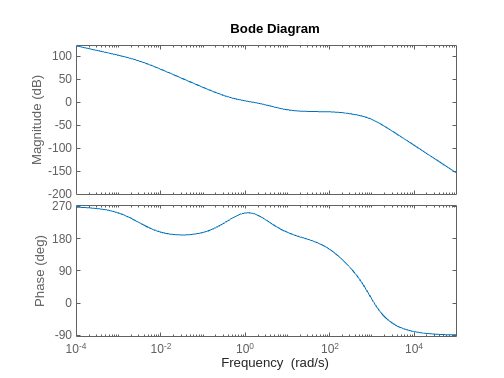


bode(G_vreft_ol)

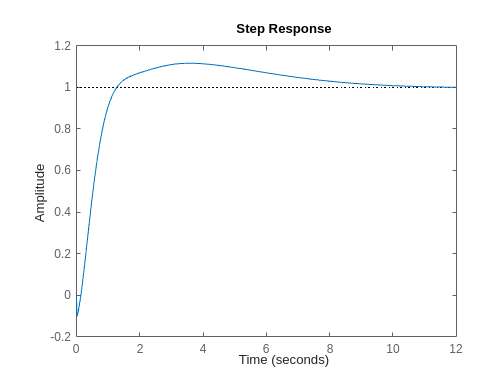

step(G_vreft_cl)

## Flush values to simulink

t_i_vreft = tau_i;
[num_lead_vreft,den_lead_vreft] = tfdata(C_D,'v');
K_vreft = Kp;

## Transfer function from vel_pre to x

% define points in model
ios(1) = linio(strcat(model,'/vel_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/x_pos'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
G_xvref = minreal(tf(num, den))

G_xvref =
 
             -3.314e04 s^9 - 4.245e07 s^8 - 9.885e09 s^7 - 5.822e11 s^6 - 7.631e12 s^5 - 5.769e12 s^4 + 4.833e14 s^3 + 3.373e15 s^2 + 8.744e15 s + 7.947e15
  --------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^12 + 2891 s^11 + 3.279e06 s^10 + 1.779e09 s^9 + 3.231e11 s^8 + 1.836e13 s^7 + 2.577e14 s^6 + 1.56e15 s^5 + 5.142e15 s^4 + 1.118e16 s^3 + 1.512e16 s^2 + 7.947e15 s
 
Continuous-time transfer function.


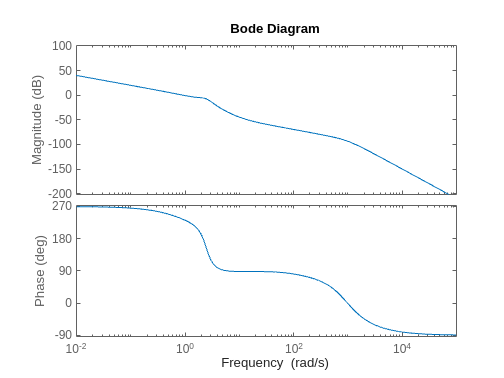

bode(G_xvref)

isstable(G_xvref)

ans = logical
   0


pole(G_xvref)

ans = 1.0e+03 *

   0.0000 + 0.0000i
  -1.2456 + 0.0000i
  -0.6903 + 0.6090i
  -0.6903 - 0.6090i
  -0.1773 + 0.0000i
  -0.0703 + 0.0000i
  -0.0068 + 0.0000i
  -0.0053 + 0.0000i
  -0.0007 + 0.0024i
  -0.0007 - 0.0024i




% Design parameters
gamma_m = gamma_xvref;
alpha = alpha_xvref;

phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_m - 180;
[mag,phase,wout] = bode(G_xvref);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));

C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  1.601 s + 1
  ------------
  0.4804 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_D*G_xvref),omega_c);
Kp = 1/mag;

G_xvref_ol = minreal(Kp*C_D*G_xvref)

G_xvref_ol =
 
            -7.581e04 s^10 - 9.716e07 s^9 - 2.268e10 s^8 - 1.346e12 s^7 - 1.829e13 s^6 - 2.41e13 s^5 + 1.097e15 s^4 + 8.409e15 s^3 + 2.483e16 s^2 + 3.068e16 s + 1.135e16
  ----------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^13 + 2893 s^12 + 3.285e06 s^11 + 1.786e09 s^10 + 3.268e11 s^9 + 1.903e13 s^8 + 2.96e14 s^7 + 2.097e15 s^6 + 8.39e15 s^5 + 2.189e16 s^4 + 3.84e16 s^3 + 3.943e16 s^2 + 1.654e16 s
 
Continuous-time transfer function.


G_xvref_cl = minreal(G_xvref_ol/(1+G_xvref_ol))

G_xvref_cl =
 
                   -7.581e04 s^12 - 9.776e07 s^11 - 2.344e10 s^10 - 1.526e12 s^9 - 2.923e13 s^8 - 1.871e14 s^7 + 6.544e14 s^6 + 1.674e16 s^5 + 1.064e17 s^4 + 3.428e17 s^3 + 5.966e17 s^2 + 5.136e17 s + 1.569e17
  --------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^15 + 2901 s^14 + 3.308e06 s^13 + 1.812e09 s^12 + 3.409e11 s^11 + 2.161e13 s^10 + 4.491e14 s^9 + 4.666e15 s^8 + 2.884e16 s^7 + 1.177e17 s^6 + 3.438e17 s^5 + 7.513e17 s^4 + 1.201e18 s^3 + 1.272e18 s^2 + 7.422e17 s + 1.569e17
 
Continuous-time transfer function.


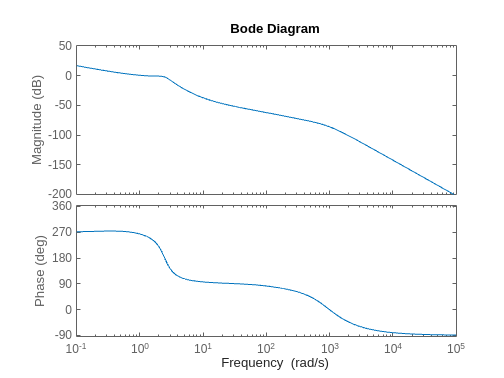


bode(G_xvref_ol)

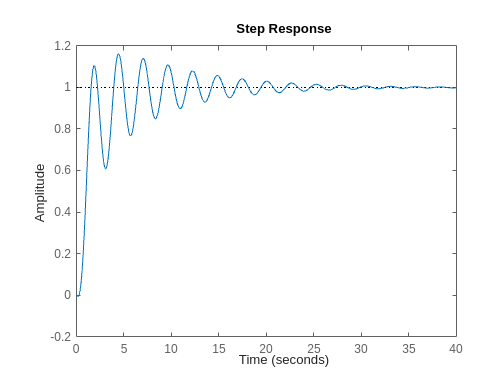

step(G_xvref_cl)

## Flush values to Simulink

[num_lead_xvref,den_lead_xvref] = tfdata(C_D,'v');
K_xvref = Kp;

## Simulation for plots

regsim = sim(model,10);

## Plots

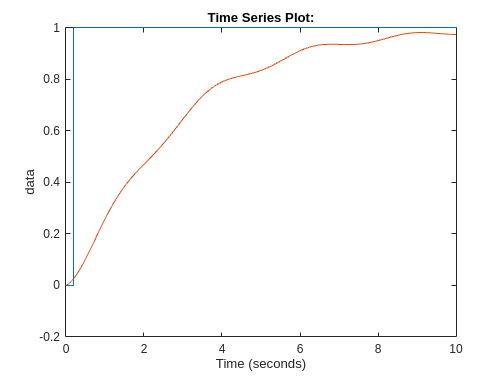

figure(1);
plot(regsim.ref);
hold on;
plot(regsim.x_pos);
hold off;

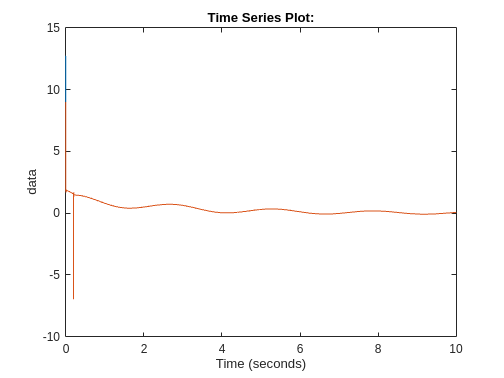


figure(2)
plot(regsim.u)
hold on;
plot(regsim.ulim);
hold off;